Signal

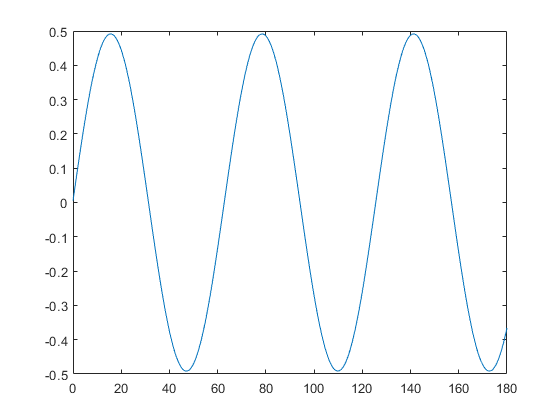

Vsig=0.5; % 1V
Wsig= 0.1; % 5 rad/s
t=0:0.5:180;
theta_sig= 0; % 45 deg
Vnoise=0.01;
Wnoise=0.1;
theta_noise=45;
noise=Vnoise.*cos(Wnoise.*t + theta_noise);
signal = Vsig.*sin(Wsig.*t+theta_sig) + noise;
plot(t,signal);

Reference

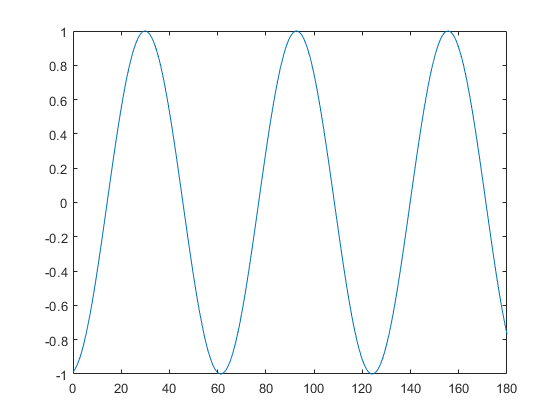

Vref=1; % 1V
Wref= 0.1; % 5 rad/s
t=0:0.5:180;
theta_ref= 30; % 45 deg 
reference = Vref.*sin(Wsig.*t+theta_ref);
plot(t,reference);

 PSD

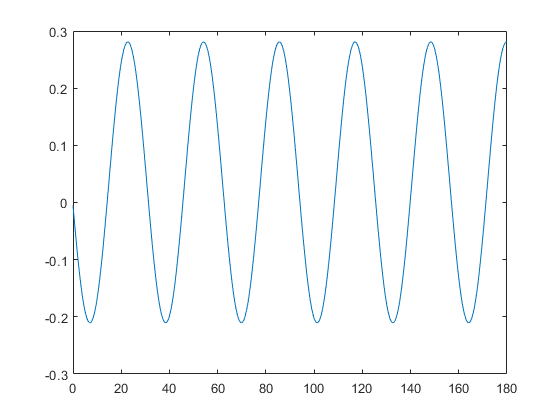

Vpsd=signal.*reference;
plot(t,Vpsd);

Fourier Transform of Vpsd

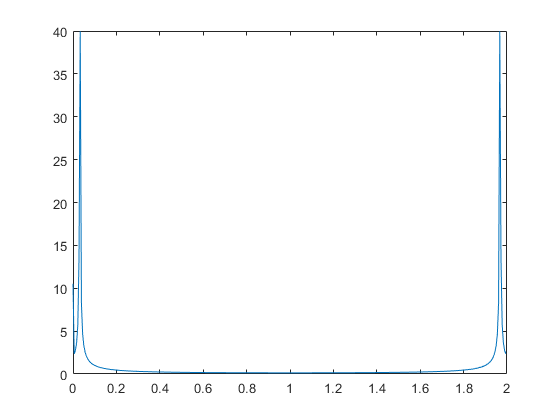

% Vpsd_freq=fft(sin(t));
Vpsd_freq=fft(Vpsd);
fs=1/0.5;
f=(0:length(Vpsd_freq)-1)*fs/length(Vpsd_freq);
plot(f,abs(Vpsd_freq))

Low Pass filter